% ROSBag file processing
close all
clear

bag = rosbag('bag/tuning_follow_test_2.bag');
topics = bag.AvailableTopics;

rabbit = select(bag,'Topic','april_cube/rabbit');

boat1 = select(bag,'Topic','/robot1/sandwich_1/sensors/p3d');


rabbitTs = timeseries(rabbit);

boat1Ts = timeseries(boat1);


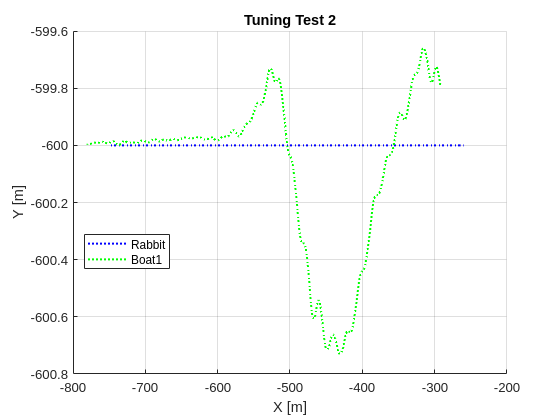

% Rabbit Position Data
rabbit_time = rabbitTs.Time;
rabbit_X = rabbitTs.Data(:,4);
rabbit_Y = rabbitTs.Data(:,5);


figure(1)
clf
grid on
hold on
plot(rabbit_X, rabbit_Y','b:','LineWidth',1.5)

% Boat Position Data


boat1_X = boat1Ts.Data(:,4);
boat1_Y = boat1Ts.Data(:,5);

% Quaternions
q_X = boat1Ts.Data(:,7);
q_Y = boat1Ts.Data(:,8);
q_Z = boat1Ts.Data(:,9);
q_W = boat1Ts.Data(:,10);

eul = rad2deg(quat2eul([q_W q_X q_Y q_Z]));
head1 = eul(:,1);

plot(boat1_X,boat1_Y,'g:','LineWidth',1.5)

legend('Rabbit','Boat1','Location','best')
title('Tuning Test 2')
xlabel('X [m]')
ylabel('Y [m]')

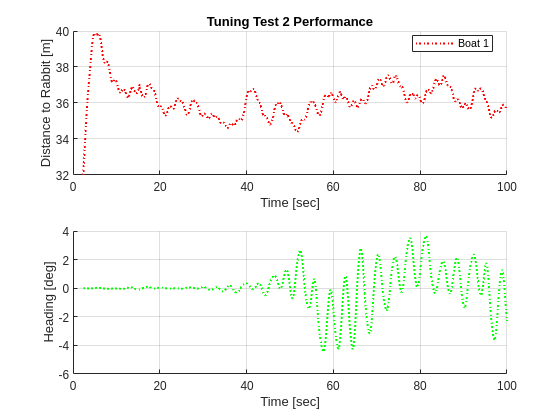

% Inter-vehicle spacing and distance to target

% Adjustments, if necessary
n1 = numel(boat1_X);
nr = numel(rabbit_X);
n = min([nr,n1]);
rabbit_time = rabbit_time((nr-n)+1:end);
% rabbit_time = rabbit_time - rabbit_time(1)
rabbit_X = rabbit_X((nr-n)+1:end);
rabbit_Y = rabbit_Y((nr-n)+1:end);

boat1_X = boat1_X((n1-n)+1:end);
boat1_Y = boat1_Y((n1-n)+1:end);


figure(2)
clf
subplot(2,1,1)
grid on
hold on
title('Tuning Test 2 Performance')
xlim([0 100])
target1 = ((rabbit_X - boat1_X).^2 + (rabbit_Y - boat1_Y).^2).^0.5;
plot(rabbit_time,target1,'r:','LineWidth',1.5)
legend('Boat 1','Location','best')
ylabel('Distance to Rabbit [m]')
xlabel('Time [sec]')



subplot(2,1,2)
grid on
hold on
plot(rabbit_time,head1,'g:','LineWidth',1.5)
ylabel('Heading [deg]')
xlabel('Time [sec]')
xlim([0 100])